% Define the low and high cutoff frequencies for the bandpass filter (in Hz)
lowCutoff = cutoffFrequencies(1)/fn % Lower cutoff frequency

lowCutoff = 0.2000

highCutoff = cutoffFrequencies(2)/fn % Upper cutoff frequency

highCutoff = 0.8000

Rp=2;
gpass= 2;
gstop= 40;

if filterType=='iir'
    if method=="butterworth"
        if type== 'lp'
            [b, a] = butter(order, lowCutoff, 'low');
        elseif type=='hp'
            [b, a] = butter(order, highCutoff, 'high');
        elseif type=='bp'
            [b, a] = butter(order, [lowCutoff, highCutoff], 'bandpass');
        elseif type=='bs'
            [b, a] = butter(order, [lowCutoff, highCutoff], 'stop');
        end
    end
    
    if method== "chebychevI"
        if type== 'lp'
            [b, a] = cheby1(order, Rp, lowCutoff,  'low');
        elseif type=='hp'
            [b, a] = cheby1(order, Rp, highCutoff, 'high');
        elseif type=='bp'
            [b, a] = cheby1(order, Rp, [lowCutoff, highCutoff], 'bandpass');
        elseif type=='bs'
            [b, a] = cheby1(order, Rp, [lowCutoff, highCutoff], 'stop');
        end
    end
    
    if method=="chebychevII"
        if type== 'lp'
            [b, a] = cheby2(order, Rp, lowCutoff, 'low');
        elseif type=='hp'
            [b, a] = cheby2(order, Rp, highCutoff, 'high');
        elseif type=='bp'
            [b, a] = cheby2(order, Rp, [lowCutoff, highCutoff], 'bandpass');
        elseif type=='bs'
            [b, a] = cheby2(order, Rp, [lowCutoff, highCutoff], 'stop');
        end
    end
    
    if method=="cauer"
        if type== 'lp'
            [b, a] = ellip(order,gpass, gstop, lowCutoff, 'low');
        elseif type=='hp'
            [b, a] = ellip(order, lowCutoff, 'high');
        elseif type=='bp'
            [b, a] = ellip(order, gpass, gstop, [lowCutoff, highCutoff], 'bandpass');
        elseif type=='bs'
            [b, a] = ellip(order, gpass, gstop, [lowCutoff, highCutoff], 'stop');
        end
    end
 
elseif filterType=='fir'
    if type=='lp'
        b = fir1(order, lowCutoff, 'low');  
        a = 1;  % denominator of 1
    elseif type=='hp'
        b = fir1(order, highCutoff, 'high');  
        a = 1;  % denominator of 1
    elseif type=='bp'
        b = fir1(order, [lowCutoff, highCutoff], 'bandpass');  
        a = 1;  % denominator of 1
    elseif type=='hp'
        b = fir1(order, [lowCutoff, highCutoff], 'stop');  
        a = 1;  % denominator of 1
    end
end

filtered_signal = filter(b,a,y);


previous:

% Ensure that time vectors match the length of the filtered signals
t = linspace(0, length(filtered_signal)/fs, length(filtered_signal));

clear ylim

if input ~= "wav"
name = type_signal;
else
name = "wav file";
end

% Define filter response with reduced points for testing
[H, w] = freqz(b, a); % Reduced to 128 points for speed


Plot original signal:

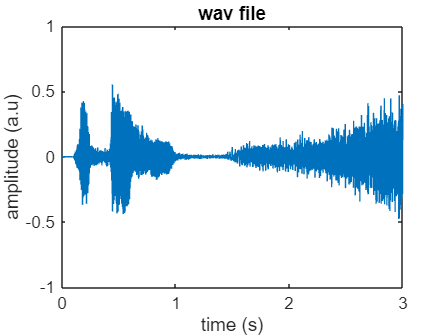

width = 15;
height = 10;
folder_name= '';

function []=paper_properties(width, height, filename)
    % Specify paper properties
    set(gcf, 'PaperUnits', 'centimeters'); % Set units to centimeters
    set(gcf, 'PaperSize', [width, height]); % Set the paper size
    set(gcf, 'PaperPosition', [0, 0, width, height]); % Set the paper position to fill the page
    print(gcf, filename, '-dpdf','-r300');
end

% plot of the original signal
figure(1);
plot(t, y);
title(name)
xlabel('time (s)');
ylabel('amplitude (a.u)')
xlim([0 xlimTime]) 
ylim([-ylimAmplitude ylimAmplitude]) 

filename = fullfile(folder_name, 'original_signal.pdf');
paper_properties(width, height, filename)

Plot filtered signal:

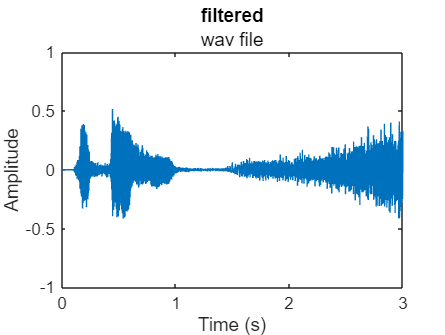

% Plot the filtered time signal with specified time and amplitude limits
figure(2);
plot(t, filtered_signal);
title("filtered", name);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 xlimTime]) 
ylim([-ylimAmplitude ylimAmplitude]) 

filename = fullfile(folder_name, 'filtered_signal.pdf');
paper_properties(width, height, filename)

Frequency response (magnitude and phase): 

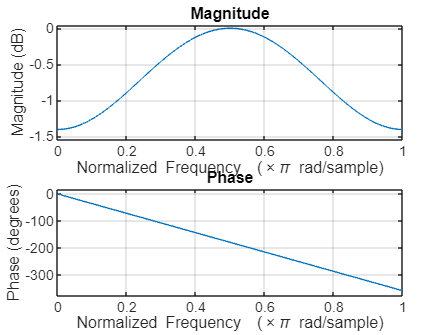

% Frequency Response (Magnitude and Phase) with specified magnitude limits
figure(3)
freqz(b,a)

filename = fullfile(folder_name, 'magnitude_phase.pdf');
paper_properties(width, height, filename)

Plot real and imaginary parts of frequency response:

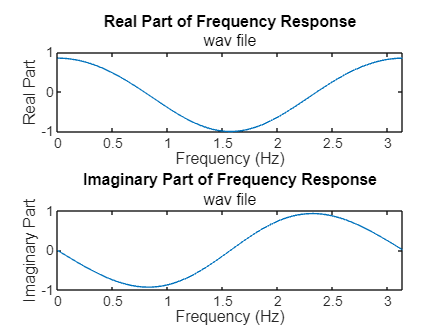

% Plot Real and Imaginary Parts of the Frequency Response
figure(4);
subplot(2, 1, 1);
plot(w, real(H)); % Real part of H
title('Real Part of Frequency Response', name);
xlabel('Frequency (Hz)');
ylabel('Real Part');

subplot(2, 1, 2);
plot(w, imag(H)); % Imaginary part of H
title('Imaginary Part of Frequency Response', name);
xlabel('Frequency (Hz)');
ylabel('Imaginary Part');

filename = fullfile(folder_name, 'real_imag.pdf');
paper_properties(width, height, filename)

Plot pole zero diagram:

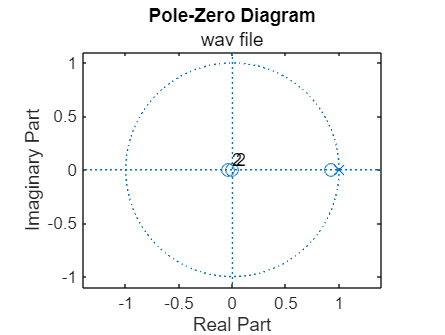

% Plot the Pole-Zero Diagram
figure(5);
zplane(b', a);
title('Pole-Zero Diagram', name);

filename = fullfile(folder_name, 'pole_zero.pdf');
paper_properties(width, height, filename)

Plot impulse response:

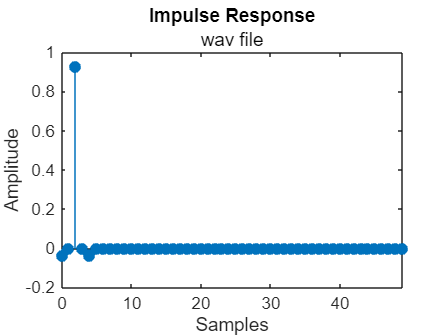

% Impulse Response of the Filter with reduced samples
figure(6);
impz(b, a, 50); % Only plot the first 50 samples
title('Impulse Response', name);
xlabel('Samples');
ylabel('Amplitude');

filename = fullfile(folder_name, 'impulse_response.pdf');
paper_properties(width, height, filename)